# Test Trained Regression Model

Copyright (c) 2018, MathWorks, Inc.

**Video**: [https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-forecasting-bitcoin-volatility-using-the-regression-learner-app-1536231842528.html](https://www.mathworks.com/videos/machine-learning-applications-in-risk-management-forecasting-bitcoin-volatility-using-the-regression-learner-app-1536231842528.html) 

System requirements

- [MATLAB® R2018b](https://www.mathworks.com/products/matlab.html)

- [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)

**Predict the volatility using the test data**

Use the trainedModel that we exported from the Regression Learner App to predict the 10-day volatility using the testing dataset (out-of-sample). 

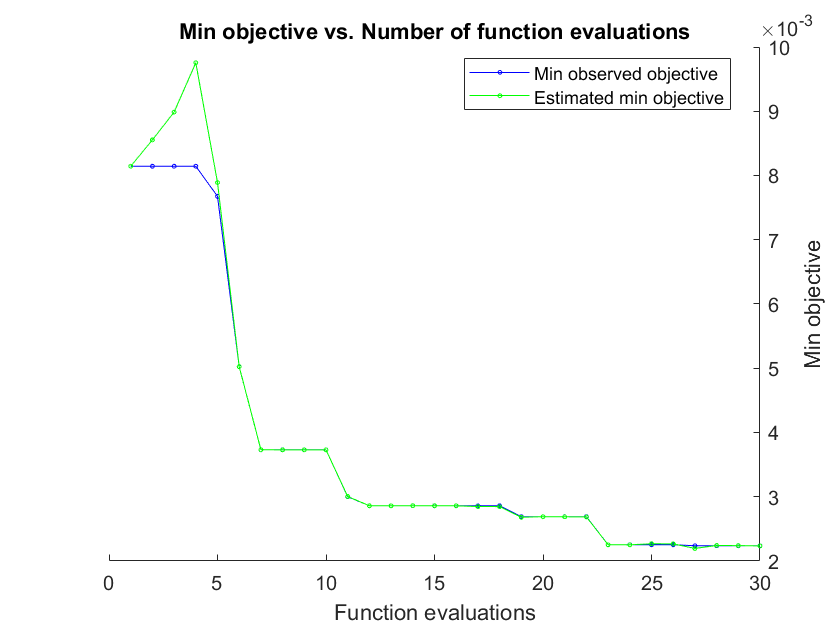

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |   0.0081441 |      3.6923 |   0.0081441 |   0.0081441 |      LSBoost |           20 |     0.075612 |            3 |
|    2 | Accept |     0.01544 |      61.594 |   0.0081441 |   0.0085542 |      LSBoost |          423 |     0.002065 |            3 |
|    3 | Accept |    0.011639 |       9.621 |   0.0081441 |   0.0089874 |          Bag |          182 |            - |          172 |
|    4 | Accept |    0.015165 |     0.69882 |   0.0081441 |   

[trainedModel, validationRMSE] = trainRegressionModel(data1_train);

yPredict = trainedModel.predictFcn(data2_test);

**Compare the predicted volatility with actual volatility**

Plot the predicted volatility VS actual volatility. Then calculate the Root-Mean Square Error (RMSE)

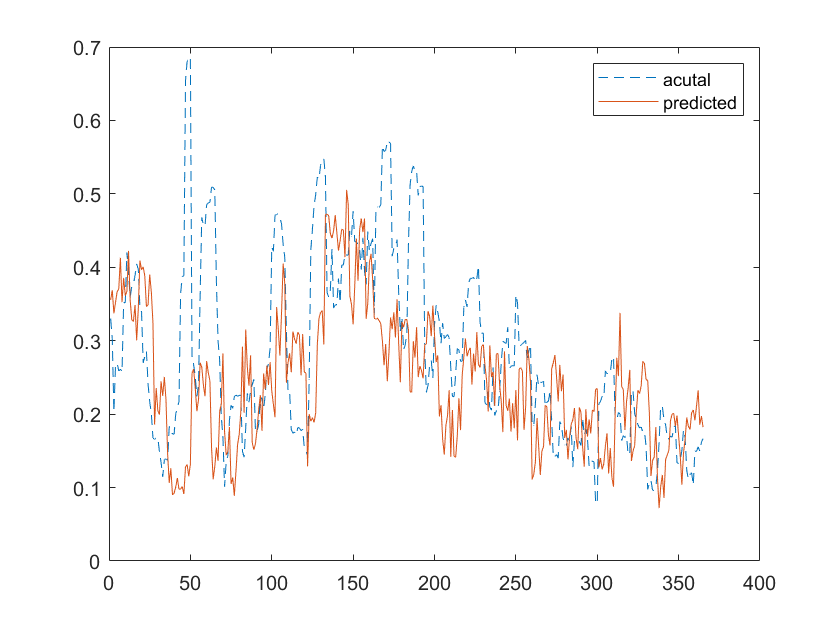

yActual = data2_test.Response;
x = 1:numel(yActual)';
plot(x,yActual,'--',x,yPredict,'-');
legend('acutal','predicted')

rsme1 = sqrt(mean((yActual - yPredict).^2))

rsme1 = 0.1299

**Use historical volatility to predict the future volatility**

Compare the predicitive performance with the case that historical volatility is used to predict the future 10-day volatility

Plot the predicted volatility VS actual volatility. Then calculate the Root-Mean Square Error (RMSE)

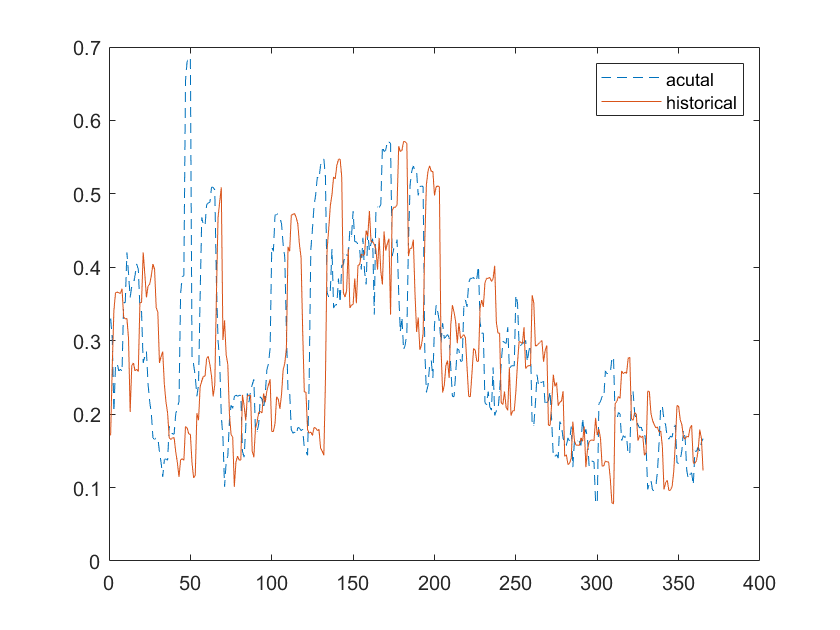

yHist = data2_test.vol10;
plot(x,yActual,'--',x,yHist,'-');
legend('acutal','historical')

rsme2 = sqrt(mean((yActual - yHist).^2))

rsme2 = 0.1451